%页码：P86
%作者；暴富
%时间：2024-07-12
%项目：example3.7
% SVFB全状态反馈，实现的轨迹追踪
%每个agennt代表1个双质量弹簧系统，共有七个节点，节点0是领导者
%每个节点有4个状态分别是物块1的位置和速度，物块2的位置和速度
%建立3维矩阵，每一列代表4个状态，一页共有7个状态，每页是进行状态迭代,即X(4,7,N)
% 矩阵A是发散的，导致系统最终也是发散的，但是不影响跟踪性能

clc
clear
lineStyles = linspecer(7); % 指定线型颜色,一页有几条线

%%状态初始化
m1 = 1.1;
m2 = 0.9;
k1 = 1.5;
k2 = 1;
c = 2;
A = [0,1,0,0;...
    (-k1-k2)/m1 0 k2/m1 0;...
    0 0 0 1;...
    k2/m2 0 -k2/m2 0];
B = [0;1/m1;0;0];
C = [1 0 0 0;...
    0 0 1 0];

%%拓扑结构初始化
%这里用Aij代表邻接矩阵
Aij = [0 0 0 0 0 0;...
    2 0 0 0 0 0;...
    0 6 0 0 0 0;...
    0 0 1 0 0 0;...
    0 0 0 1 0 0;...
    0 0 0 0 3 0];
L = diag(sum(Aij,2)) - Aij;
G = diag([1,0,0,0,0,0]);

%%计算控制器增益，即反馈矩阵K
%stabilizable稳定性分析，转化为可控性分析
Rc = ctrb(A,B);
rank(Rc); %ans = 4结果可控
Q = eye(4); %想要收敛快点就增大对角值
R = 1;
[K,P] = lqr(A,B,Q,R) ;

%%仿真初始化
Ts = 0.01;
t = 0:Ts:25;
N = length(t);

%%agent初始化,7个agent，一个agent4个状态，每一页对应状态迭代
X = zeros(4,6,N);
X0 = zeros(4,1,N);
%设置随机状态
X_initial = randn(4,6);
X(:,:,1) = X_initial;
X0_initial = randn(4,1);
X0(:,:,1) = X0_initial;

## **原始系统**

**1.跟随者**


$$$\dot{x}_i=Ax_i+cBK\Bigg(\sum_{j=1}^Na_{ij}(x_j-x_i)+g_i(x_0-x_i)\Bigg)$$$



$$$$
\dot{x}_0\,\,=\,\,Ax_0
$$
$$


### 2.领导者：


$$$$
\dot{x}_0\,\,=\,\,Ax_0
$$
$$


## **离散后**

**1.跟随者**


$$$$
x_i(k+1)=x_i(k)+T_s\Bigg(Ax_i(k)+\mathrm{cBK\Bigg(}\sum_{j=1}^N{a_{ij}}(x_j(k)-x_i(k))+g_i\left( x_0\left( k \right) -x_i\left( k \right)\Bigg )\Bigg )
$$
$$



$$$$
x_0\left( k+1 \right) \,\,=\,x_0\left( k \right) +T_s*\,Ax_0\left( k \right) \,\,
$$
$$


### 2.领导者：


$$$$
\dot{x}_0(k)\,\,=\,\,Ax_0(k)
$$
$$


### 定义：


$$$
sum\_temp = \sum_{j=1}^N{a_{ij}}(x_j(k)-x_i(k))
$$$



$$$
sum\_leader = g_i\left( x_0\left( k \right) -x_i\left( k \right))
$$$


## 整理的：

**1.跟随者**


$$$$
x_i(k+1)=x_i(k)+T_s\Bigg(Ax_i(k)+\mathrm{cBK*\Bigg(sum\_temp+sum\_leader\Bigg)\Bigg )
$$$$



$$$$
x_0\left( k+1 \right) \,\,=\,x_0\left( k \right) +T_s*\,Ax_0\left( k \right) \,\,
$$
$$


### 2.领导者：


$$$$
\dot{x}_0(k)\,\,=\,\,Ax_0(k)
$$
$$


## 拓扑结构

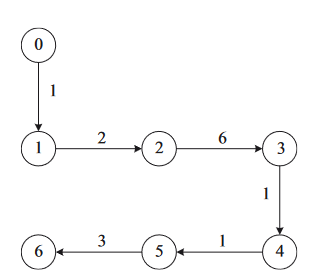

%%循环程序
% 矩阵A是发散的，导致系统最终也是发散的，但是不影响跟踪性能
for k = 2:N
    X0(:,1,k) = X0(:,1,k-1) + Ts*(A*X0(:,1,k-1)) ;
    for i = 1:6
        sum_term = 0;
        sum_leader = G(i,i)*(X0(:,1,k-1)-X(:,i,k-1));
        for j = 1:6
            sum_term = sum_term + Aij(i,j)*(X(:,j,k-1)-X(:,i,k-1));          
        end
          X(:,i,k) = X(:,i,k-1) + Ts*(A*X(:,i,k-1)+c*B*K*(sum_term + sum_leader));
    end   
end

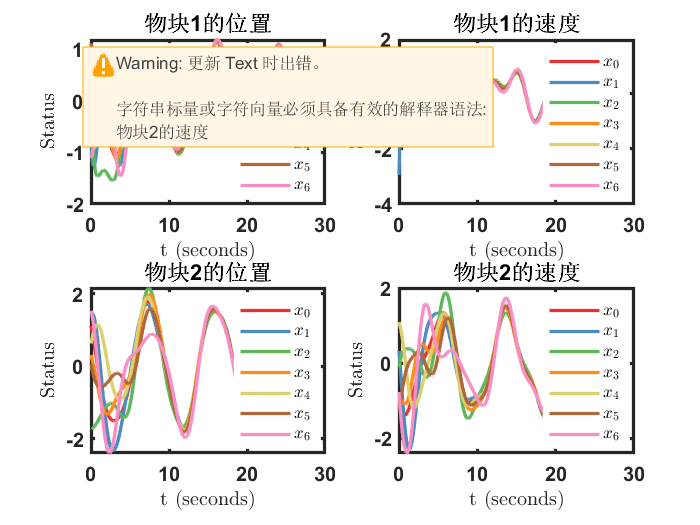

%%绘图
%% 绘制结果
hf = figure;  %新建 图形控制句柄
hf.Color= [1 1 1]; % 控制图形的整体颜色。（scope中被默认为灰黑色，此处修改为白色）

subplot(2,2,1)
plot(t,reshape(X0(1,1,:),1,N),'Color',lineStyles(1,:),'linestyle','-','linewidth',2); 
hold on
plot(t,reshape(X(1,1,:),1,N),'Color',lineStyles(2,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X(1,2,:),1,N),'Color',lineStyles(3,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X(1,3,:),1,N),'Color',lineStyles(4,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X(1,4,:),1,N),'Color',lineStyles(5,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X(1,5,:),1,N),'Color',lineStyles(6,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X(1,6,:),1,N),'Color',lineStyles(7,:),'linestyle','-','linewidth',2); 
FigPorperty('t (seconds)','Status','物块1的位置')

subplot(2,2,2)
plot(t,reshape(X0(2,1,:),1,N),'Color',lineStyles(1,:),'linestyle','-','linewidth',2); 
hold on
plot(t,reshape(X(2,1,:),1,N),'Color',lineStyles(2,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X(2,2,:),1,N),'Color',lineStyles(3,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X(2,3,:),1,N),'Color',lineStyles(4,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X(2,4,:),1,N),'Color',lineStyles(5,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X(2,5,:),1,N),'Color',lineStyles(6,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X(2,6,:),1,N),'Color',lineStyles(7,:),'linestyle','-','linewidth',2); 
FigPorperty('t (seconds)','Status','物块1的速度')

subplot(2,2,3)
plot(t,reshape(X0(3,1,:),1,N),'Color',lineStyles(1,:),'linestyle','-','linewidth',2); 
hold on
plot(t,reshape(X(3,1,:),1,N),'Color',lineStyles(2,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X(3,2,:),1,N),'Color',lineStyles(3,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X(3,3,:),1,N),'Color',lineStyles(4,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X(3,4,:),1,N),'Color',lineStyles(5,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X(3,5,:),1,N),'Color',lineStyles(6,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X(3,6,:),1,N),'Color',lineStyles(7,:),'linestyle','-','linewidth',2); 
FigPorperty('t (seconds)','Status','物块2的位置')

subplot(2,2,4)
plot(t,reshape(X0(4,1,:),1,N),'Color',lineStyles(1,:),'linestyle','-','linewidth',2); 
hold on
plot(t,reshape(X(4,1,:),1,N),'Color',lineStyles(2,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X(4,2,:),1,N),'Color',lineStyles(3,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X(4,3,:),1,N),'Color',lineStyles(4,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X(4,4,:),1,N),'Color',lineStyles(5,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X(4,5,:),1,N),'Color',lineStyles(6,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X(4,6,:),1,N),'Color',lineStyles(7,:),'linestyle','-','linewidth',2); 
FigPorperty('t (seconds)','Status','物块2的速度')